get_path = "D:\Programming\Programe MatLab\ImageProcessing\chest-xray-classifier\data\raw";
first_file = dir(get_path);

for i = 3:length(first_file)
    second_file = dir(get_path + '\' + first_file(i).name);
    for j = 3:length(second_file)
        images = dir(get_path + '\' + first_file(i).name + '\' + second_file(j).name);
        images = images(~[images.isdir]);
        for k = 1:length(images)
            img = ImageProcessing(get_path + '\' + first_file(i).name + '\' + second_file(j).name + '\' + images(k).name);
            img.Brightness_Contrast(-1.8,1.8);
            if img.Layers() == 3
                img.RGB2GrayScale();
            end
            % Save
        end
    end
end

D:\Programming\Programe MatLab\ImageProcessing\chest-xray-classifier\data\raw\test\COVID19\COVID19(460).jpg
D:\Programming\Programe MatLab\ImageProcessing\chest-xray-classifier\data\raw\test\COVID19\COVID19(461).jpg
D:\Programming\Programe MatLab\ImageProcessing\chest-xray-classifier\data\raw\test\COVID19\COVID19(462).jpg
D:\Programming\Programe MatLab\ImageProcessing\chest-xray-classifier\data\raw\test\COVID19\COVID19(463).jpg
D:\Programming\Programe MatLab\ImageProcessing\chest-xray-classifier\data\raw\test\COVID19\COVID19(464).jpg
D:\Programming\Programe MatLab\ImageProcessing\chest-xray-classifier\data\raw\test\COVID19\COVID19(465).jpg
D:\Programming\Programe MatLab\ImageProcessing\chest-xray-classifier\data\raw\test\COVID19\COVID19(466).jpg
D:\Programming\Programe MatLab\ImageProcessing\chest-xray-classifier\data\raw\test\COVID19\COVID19(467).jpg
D:\Programming\Programe MatLab\ImageProcessing\chest-xray-classifier\data\raw\test\COVID19\COVID19(468).jpg
D:\Programming\Programe MatL

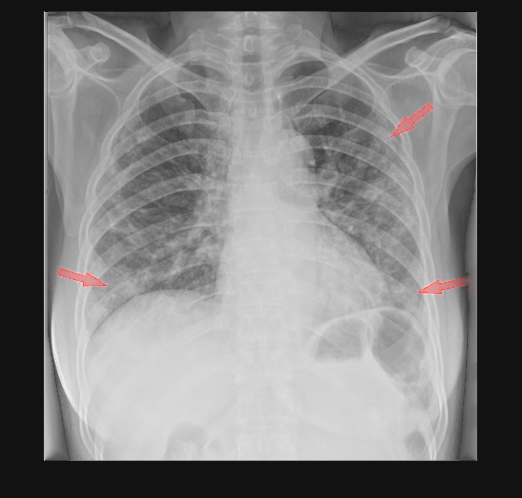

%TEST

img = ImageProcessing("D:\Programming\Programe MatLab\ImageProcessing\chest-xray-classifier\data\raw\test\COVID19\COVID19(553).jpg");
img.Display_Image();

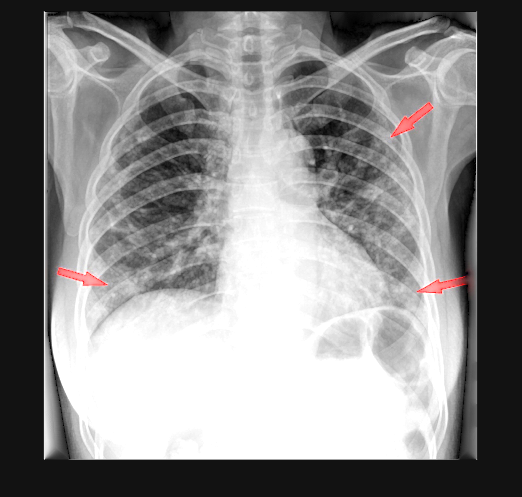

img.Brightness_Contrast(-1.8,1.8);
img.Display_Image();

img.Layers()

ans = 3

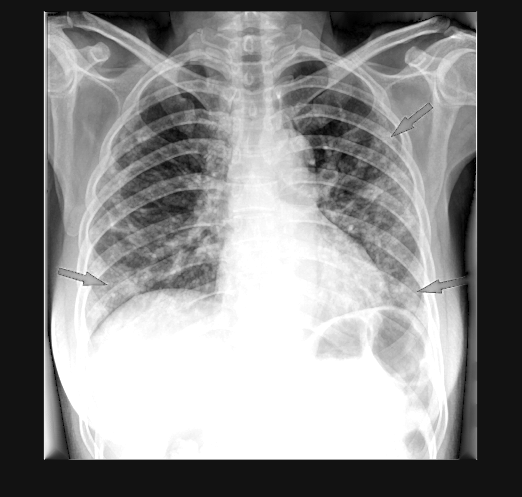

if img.Layers() == 3
    img.RGB2GrayScale();
end
img.Display_Image();